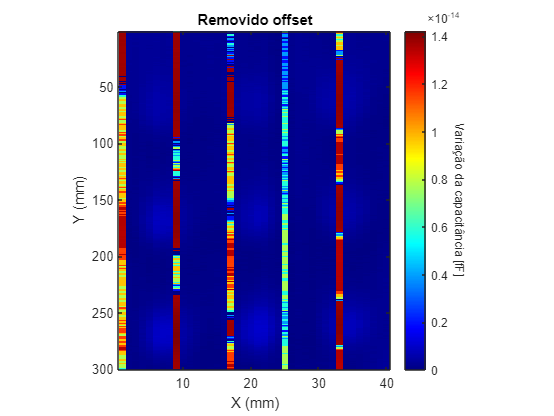

clear all;
load Calibracao.mat
%load Dados\04_dez\linhas2.mat;
load Dados\13_02\3x3.mat
%load Cap_board_data.mat
%% Se necessário remoção de canais defeituosos
j = [1,8,16,24,32,40]; %Figura 3x3
%j = [1,9,17,25,33,41]; %Linhas
j= [1:80]; %A figura linhas2 recortou-se o primeiro scan devido ao grande ruido inicial

%Cap_board_data(j,:) =[];
%j= [1];
%Cap_board_data(j,:) =[];
%j = [9,17,25,33,41];
%j= [8,16,24,32];

%% Definição de parametros
numero_sensores = 8;
numero_colunas = size(Cap_board_data,2);
numero_amostras = height(Cap_board_data);
A =[];
B =[];
CC =[];
i = 1;
C = Cap_board_data;
x=linspace(0,(numero_colunas/numero_sensores*Res_x),numero_colunas);
x = round(x);
y=linspace(0,numero_amostras*Res_y,height(Cap_board_data));
%y=round(y);
%% Remoção do offset de cada canal
for k=1:numero_colunas
    m = mod(k,numero_sensores);
    if m == 0
        m=numero_sensores;
    end
    A(:,k) = C(:,k) - Calibra_linha(3,m);
    %A(:,k) = C(:,k) - C(6,k);
    %A(:,k) = C(:,k) - Calibration(:,m);
    CC(:,k) = C(:,k) - min(C(:,k));
end

if false%Se check a remoção por calibração é feita, do contrario a por média
    offset_data = A;
else
    offset_data = CC;
end
%%%%%%%%%%%%%%%%%%%%%%%
figure
imagesc(offset_data)
%imagesc(Cap_board_data)
pbaspect([1 1 1])
pbaspect([numero_colunas*6/(numero_amostras) 1 1])
title("Removido offset")
cb1 =colorbar();
ylabel(cb1,"Variação da capacitância [fF]",Rotation=270)
colormap("jet")
xlabel ("X (mm)")
ylabel ("Y (mm)")


detrendedData = detrend(offset_data);

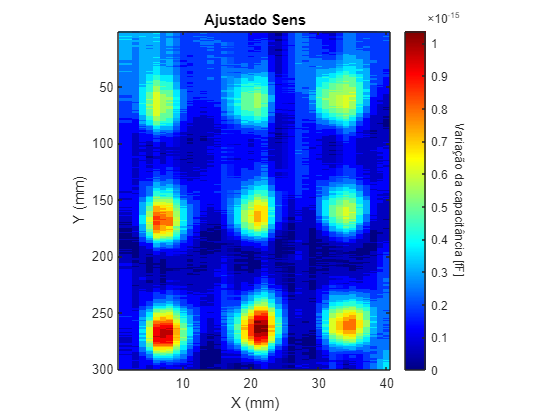

M = offset_data;
for i = 0:(numero_colunas/numero_sensores)
    for k = 1:numero_sensores
       sensor_max(i+1,k) = max(M(:,k+i));
       sensor_min(i+1,k) = min(M(:,k+i));
    end
end
sensor_sens = sensor_max - sensor_min;
sensor_sens = mean(sensor_max - sensor_min);
M_sens = [];
for k=1:numero_colunas
    m = mod(k,numero_sensores);
    if m == 0
        m=numero_sensores;
    end
    %M_sens(:,k) = offset_data(:,k)*(max(sensor_sens)/sensor_sens(m));
    M_sens(:,k) = M(:,k)/sensor_sens(m);
    M_cali(:,k) = M(:,k)/M(282,k);
    %M_cali(:,k) = M(:,k)/(Calibra_linha(4,m)-Calibra_linha(3,m));
end
if false%Se check a calibração é feita por dados, do contrario pela medição do ar e metal
    cali_data = M_cali;
else
    cali_data = M; %Sem calibracao
end
j = [40];
%cali_data(:,j) =cali_data(:,j-1);
j = [1];
cali_data(:,j) =cali_data(:,j+1);
j =[3,8,11,16,19,24,27,32,35];
j = [9,17,25,33];
cali_data(:,j) = (cali_data(:,j-1)+cali_data(:,j+1))/2;

figure
imagesc(cali_data)
pbaspect([1 1 1])
pbaspect([numero_colunas*6/(numero_amostras) 1 1])
title("Ajustado Sens")
cb1 =colorbar();
ylabel(cb1,"Variação da capacitância [fF]",Rotation=270)
colormap("jet")
xlabel ("X (mm)")
ylabel ("Y (mm)")

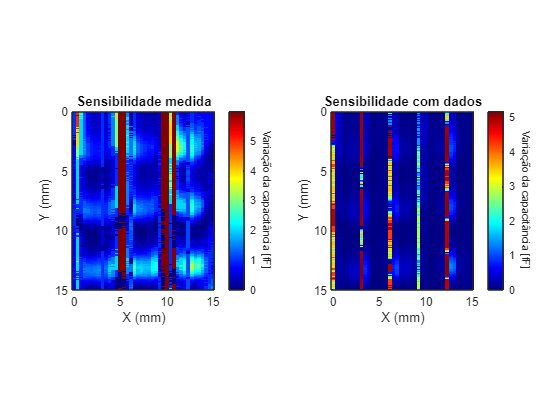

figure
tiledlayout(1,2)
nexttile
imagesc(x,y,M_cali)
pbaspect([1 1 1])
pbaspect([numero_colunas*6/(numero_amostras) 1 1])
title("Sensibilidade medida")
cb1 =colorbar();
ylabel(cb1,"Variação da capacitância [fF]",Rotation=270)
colormap("jet")
xlabel ("X (mm)")
ylabel ("Y (mm)")
nexttile
imagesc(x,y,M_sens)
title("Sensibilidade com dados")
%pbaspect([1 1 1])
pbaspect([numero_colunas*6/(numero_amostras) 1 1])
cb1 =colorbar();
ylabel(cb1,"Variação da capacitância [fF]",Rotation=270)
colormap("jet")
xlabel ("X (mm)")
ylabel ("Y (mm)")

## Trecho para calculo do SNR no caso da proveta 3x3

% yn = 30;
% xn = 200;
% CCO = cali_data;
% Circle_SNR(CCO,7,269,yn,xn) %3x1
% Circle_SNR(CCO,21,264,yn,xn) %3x2
% Circle_SNR(CCO,35,262,yn,xn) %3x3
% Circle_SNR(CCO,7,167,yn,xn) %2x1
% Circle_SNR(CCO,21,164,yn,xn) %2x2
% Circle_SNR(CCO,34,161,yn,xn) %2x3
% Circle_SNR(CCO,6,65,yn,xn) %1x10.59
% Circle_SNR(CCO,21,65,yn,xn) %1x2
% Circle_SNR(CCO,34,64,yn,xn) %1x3


## Trecho para calculo do SNR no caso 4 pontos

% yn = 5; 
% xn = 240;
% 
% Circle_SNR(CCO,32,48,yn,xn) % dir_sup
% Circle_SNR(CCO,7,113,yn,xn) %esq_sup
% Circle_SNR(CCO,15,301,yn,xn) %esq_inf
% Circle_SNR(CCO,37,230,yn,xn) %dir_inf


## Trecho para calculo do SNR no caso das linhas

% yn = 16;
% xn = 14;
% Line_SNR(cali_data,21,84,yn,xn) %1° linha
% Line_SNR(cali_data,21,146,yn,xn) %2° linha
% Line_SNR(cali_data,21,218,yn,xn) %3° linha
% Line_SNR(cali_data,21,281,yn,xn) %4° linha

% 
% %% Signal Noise
% signal = 0;
% area = 2;
% n=0;
% pixels =0;
% 
% %%
% Matriz = CCO;
% [row_max, col_max] = find(ismember(Matriz, max(Matriz(:))));
% [row_min, col_min] = find(ismember(Matriz, min(Matriz(:))));
% for i=-area:area
%     for j=-area:area
%         signal = Matriz(row_max+i,col_max+j)+ signal; %No caso dos buracos
%         %signal = abs(Matriz(row_min+i,col_min+j))+ signal; %No caso dos pistões
%         pixels=pixels+1;
%     end
% end
% signal = signal/pixels;
% noise = sum(sum(Matriz.^2))/numel(Matriz);
% Teste = "Sem ajuste de sensibilidade"
% SNR = 10*log10(signal^2/noise)
% sensitivity = mean(Matriz(row_max,col_max),'all') - mean(Matriz(row_min,col_min),'all')

f = figure

f =   Figure (4) with properties:

      Number: 4
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 458 560 420]
       Units: 'pixels'

  Show all properties


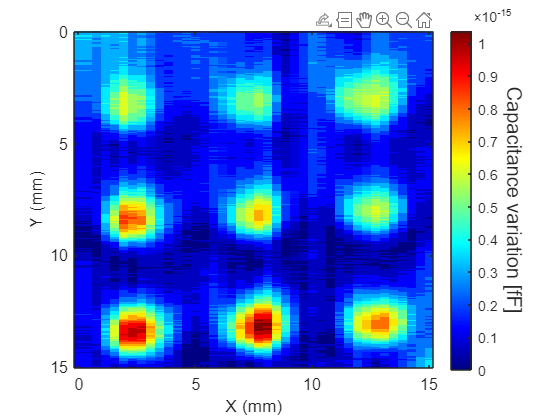


imagesc(x,y,cali_data(:,:));
fontsize(12,"points")
pbaspect([numero_colunas*(numero_sensores)/(numero_amostras) 1 1])
cb1 =colorbar();
ylabel(cb1,"Capacitance variation [fF]", Rotation=270,FontSize=15)
colormap("jet")
xlabel ("X (mm)",FontSize=13)
ylabel ("Y (mm)",FontSize=13)
exportgraphics(f,'Image.png','Resolution',300)

function Circle_SNR(Matriz,ys,xs,yn,xn)
    %% Funcao criada para calcular o SNR de circunferencias, xs e ys dizem respeito a cordenada de centro do circulo e xn,yn do ruido.
    signal_max = 0;
    signal_min = 0;
    area = 4;
    pixels = 0;
    sum = 0;
    %Calcular a média de cada uma das features e depois a média de um espaço
    %que seja ruido, feature-ruido=sinal e depois divide
    %O sinal é a me´dia do max - a nedia do menor, e o rudio é o std do
    %ponto de minimo
    %%
    for i=-area:area
        for j=-area:area
            signal_max = (Matriz(xs+i,ys+j)) + signal_max; %No caso dos buracos
            %signal = abs(Matriz(x+i,y+j))+ signal; %No caso dos pistões
            signal_min = (Matriz(xn+i,yn+j)) + signal_min;
            pixels=pixels+1;
        end
    end
    signal_min = signal_min/pixels;
    signal_max = signal_max/pixels;

       for i=-area:area
        for j=-area:area
            sum = sum + (Matriz(xn+i,yn+j)-signal_min)^2;
        end
       end

    signal = (signal_max-signal_min)
    noise = sqrt(sum/(pixels-1))
    S = 10*log10(signal/noise)
    sensitivity = mean(Matriz(xs,ys),'all') - mean(Matriz(xn,yn),'all')
end
function Line_SNR(Matriz,ys,xs,yn,xn)
    signal = 0;
    noise = 0;
    altura = 6
    largura = 12;
    pixels =0;
    %Calcular a média de cada uma das features e depois a média de um espaço
    %que seja ruido, feature-ruido=sinal e depois divide
    %%
    for i=-largura:largura
        for j=-altura:altura
            signal = (Matriz(xs+i,ys+j))^2 + signal; %No caso dos buracos
            %signal = abs(Matriz(x+i,y+j))+ signal; %No caso dos pistões
            noise = (Matriz(xn+i,yn+j)^2) + noise;
            pixels=pixels+1;
        end
    end
    signal = signal/pixels
    noise = noise/pixels
    S = 10*log10(signal/noise)
    sensitivity = mean(Matriz(xs,ys),'all') - mean(Matriz(xn,yn),'all')
end